## **FFT仿真实验**

% 清理工作空间和命令窗口
clear all;
close all;
clc;


### **模拟信号发生器**

生成一个完整周期的时域模拟信号（利用足够多的点数逼近）

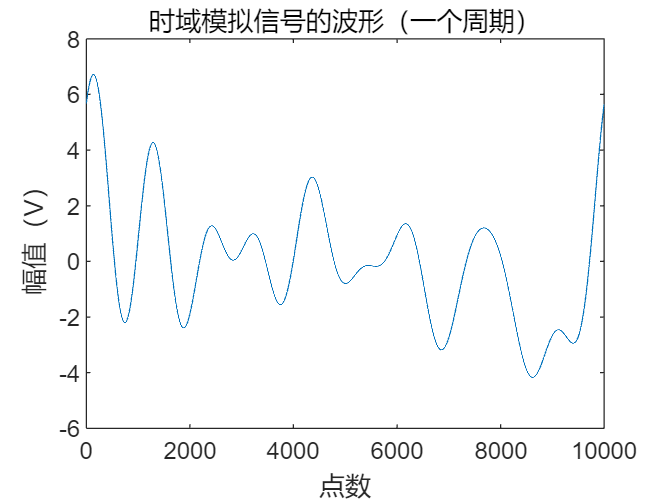

% --- 定义混合波形的谐波参数矩阵 ---
f_fundamental = 1000;   % 基波频率
C_offset = 0;       % 整个混合波形的直流偏置 (通常为 0)
% 矩阵的每一行： [ 幅值 (A), 相位 (Phase in radians) ]
% 行号 i 对应 第 i 次谐波
harmonic_params_matrix = [
    1.0, 0;       % 第 1 次谐波 (基波): 幅值 1.0, 相位 0 弧度
    1.0, pi/4;       % 第 2 次谐波: 幅值 0.0 (不包含二次谐波)
    1.0, pi/6;    % 第 3 次谐波: 幅值 0.5, 相位 pi/4 弧度 (45度)
    1.0, pi/3;      % 第 4 次谐波: 幅值 0.2, 相位 pi 弧度 (180度)
    1.0, pi/2;
    1.0, pi;
    1.0, pi/3;
    1.0, pi/3;
    1.0, pi/3;
    1.0, 0;
    % ... 你可以在这里继续添加更多谐波的参数 ...
    % 例如: 0.1, pi/2; % 第 5 次谐波: 幅值 0.1, 相位 pi/2 弧度
];
L_high = 10000;     % 生成一个周期所需的点数，点数越高越接近模拟信号
% 创建点的序号向量 (从 0 到 L_high-1)
k = 0:L_high-1;
% 获取矩阵的行数，即包含的最高谐波次数 (或者说参与叠加的项数)
num_harmonics = size(harmonic_params_matrix, 1);
% 初始化
time_analog_signal = C_offset * ones(1, L_high);
% 循环叠加各个谐波分量
for i = 1:num_harmonics
    % 当前处理的是第 i 次谐波
    harmonic_number = i;

    % 从矩阵中提取当前谐波的幅值和相位
    A_i = harmonic_params_matrix(i, 1);
    Phase_i = harmonic_params_matrix(i, 2);

    % 生成当前谐波的高分辨率单周期波形分量
    % 频率是基波的 i 倍
    harmonic_component = A_i * sin(2*pi * harmonic_number * k / L_high + Phase_i);

    % 将当前谐波分量叠加到总波形中
    time_analog_signal = time_analog_signal + harmonic_component;
end



figure;
plot(k, time_analog_signal); % 可以直接以点序号为x轴
ylabel('幅值（V）');xlabel('点数');
title('时域模拟信号的波形（一个周期）');


fprintf('混合波形的组成参数 (基波频率 f = %.2f Hz):\n', f_fundamental);

混合波形的组成参数 (基波频率 f = 1000.00 Hz):


fprintf('---------------------------------------------------\n');

---------------------------------------------------


fprintf('直流偏置 (DC Offset): %.4g\n', C_offset);

直流偏置 (DC Offset): 0


fprintf('---------------------------------------------------\n');

---------------------------------------------------


fprintf('谐波分量 (Harmonics):\n');

谐波分量 (Harmonics):


fprintf('---------------------------------------------------\n');

---------------------------------------------------


fprintf('次数 | 幅值 (A) | 相位 (degree)\n');

次数 | 幅值 (A) | 相位 (degree)


fprintf('---------------------------------------------------\n');

---------------------------------------------------



% 遍历参数矩阵，打印出所有幅值非零的谐波参数
for i = 1:num_harmonics
    A_i = harmonic_params_matrix(i, 1);
    Phase_i = harmonic_params_matrix(i, 2) / pi * 180;
    harmonic_number = i;
    if abs(A_i) > 1e-9 % 仅打印幅值非零的谐波的参数信息
        fprintf('%4d | %8.4g | %9.4g\n', harmonic_number, A_i, Phase_i);
    end
end

   1 |        1 |         0
   2 |        1 |        45
   3 |        1 |        30
   4 |        1 |        60
   5 |        1 |        90
   6 |        1 |       180
   7 |        1 |        60
   8 |        1 |        60
   9 |        1 |        60
  10 |        1 |         0


fprintf('---------------------------------------------------\n');

---------------------------------------------------


### 模拟ADC采样过程

采样N个点

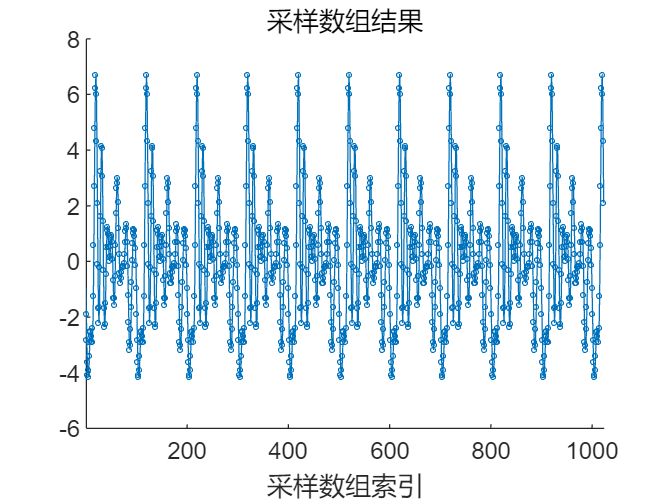

N = 1024;            % 模拟单片机采样的总点数
Fs = 100000;      % 采样频率

% 每个周期采样的点数
N_sample_aver_T = Fs / f_fundamental;
% 取点间隔
sampling_step_in_high_res_indices = L_high / N_sample_aver_T;
% -----------------------------------------------------------------------
% --- 模拟采样过程：基于固定步长和周期循环抽取点 ---
% -----------------------------------------------------------------------

% 创建一个向量，代表我们要抽取的 N_sample 个采样点的序号 (从 0 开始到 N_sample-1)
k_sampled_indices_0based = 0:N-1;

% 抽取的起点受到随机初始相位的影响
% 是否启动随机初始相位，若不启动则令rand_phase=0
% （启用会导致每次采样的结果数组波形一致但是起始相位随机）
rand_phase = 2 * pi * rand;
sample_begin_index = rand_phase / (2 * pi) * L_high;

% 计算这 N_sample 个采样点在 time_analog_signal 中的对应索引
% 计算逻辑:
% 从高分辨率波形的“起始”点开始 (概念上的第 0 个索引)
% 第 k 个采样点 (0-indexed k) 对应在原始波形“展开后”的索引位置是 k * sampling_step_in_high_res_indices
% 将这个位置 "卷绕" 到第一个周期内 (长度为 L_high) 的索引范围 [0, L_high-1]： mod(k * sampling_step_in_high_res_indices, L_high)
% 转换为 MATLAB 的 1-based 索引范围 [1, L_high]： mod(k * sampling_step_in_high_res_indices, L_high) + 1

sample_indices_in_high_res = mod(round(k_sampled_indices_0based * sampling_step_in_high_res_indices + sample_begin_index), L_high) + 1;

% --- 从高分辨率单周期波形中提取这些索引对应的值 ---
% 这些值就是模拟单片机 ADC 采集到的结果
adcResult = time_analog_signal(sample_indices_in_high_res);
figure;
hold on;
% plot(k_sampled_indices_0based, adcResult, '-o'); % 可以直接以点序号为x轴
plot(k_sampled_indices_0based, adcResult, '-o', MarkerSize=2); % 可以直接以点序号为x轴
xlabel('采样数组索引');
title('采样数组结果')
xlim([1 N])

fprintf('采样数组的采到波形的初始相位%.2f°,\n采样频率为%.1f, \n信号基波频率为%.1f,\n一个周期的点数约为%.2f,\n采样数组中包含的周期个数为%.2f', rand_phase / (2 * pi) * 360, Fs, f_fundamental, N_sample_aver_T, N / N_sample_aver_T);

采样数组的采到波形的初始相位293.30°,
采样频率为100000.0, 
信号基波频率为1000.0,
一个周期的点数约为100.00,
采样数组中包含的周期个数为10.24

### 加窗处理

% --- 加窗处理 ---

% 假设你的时域信号数据是 adcResult
% 信号的实际长度
L_signal = length(adcResult);

% 1. 选择并生成窗函数
% 窗函数的长度通常与你要分析的信号段长度相同。
% 这里使用 Hanning 窗，长度为 L_signal
% window = hann(L_signal);    % Hanning 窗
window = flattopwin(L_signal);% 平顶窗（测幅度数组最好的）
% window = rectwin(L_signal); % 如果不加窗，相当于使用矩形窗
% window = hamming(L_signal); % Hamming 窗
% window = blackman(L_signal);% Blackman 窗

% 2. 将时域信号与窗函数逐点相乘
% 这就是“加窗”操作
adcResult_windowed = adcResult(:) .* window(:); % 使用 (:) 确保逐点乘法正确进行

### 进行FFT

% --- 1. 执行 N_fft 点 FFT ---
N_fft = 1024;
fft_result = fft(adcResult_windowed, N_fft);
% --- 2. 计算完整的幅度谱和相位谱 ---
% abs() 计算复数的幅度
magnitude_full = abs(fft_result);
% angle() 计算复数的相位 (单位是弧度)
phase_full = angle(fft_result);

% --- 3. 提取单边谱 (0Hz 到 Fs/2) ---
% 单边谱包含 DC 分量 (索引 1) 和所有正频率分量
% 如果 N_fft 是偶数，单边谱到索引 N_fft/2 + 1 (包含 fs/2)
% 如果 N_fft 是奇数，单边谱到索引 (N_fft+1)/2 (不包含 fs/2)
num_single_sided_points = floor(N_fft/2) + 1; % 计算单边谱的点数

% 提取单边幅度谱数据
magnitude_single_sided = magnitude_full(1:num_single_sided_points);
% 提取单边相位谱数据
phase_single_sided = phase_full(1:num_single_sided_points);

% --- 4. 缩放单边幅度谱 ---
% 标准的单边幅度谱缩放：
% 除了 DC 分量 (索引 1) 和奈奎斯特频率分量 (如果 N_fft 是偶数，索引 N_fft/2 + 1) 外，其他点乘以 2
% 然后所有点都除以 N_fft

因此归一化是需要除原始信号长度

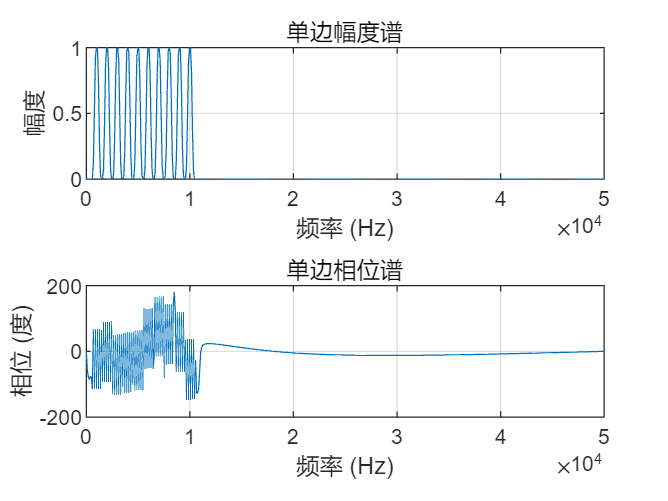


% 加窗产生的幅值削减进行补偿（进行基于窗函数总和的缩放）
window_sum = sum(window);
magnitude_single_sided = magnitude_single_sided / window_sum;
% 注意如果进行了窗函数修正，就不需要进行下面的归一化了，因为窗函数修正包含了归一化
% magnitude_single_sided = magnitude_single_sided / N; % 先除以 N_signal 进行归一化

% 对非 DC 和非奈奎斯特点乘以 2
% 这里我们选择从第二个点到倒数第二个点进行乘以 2 的操作
% 这正确地处理了除 DC 和可能的奈奎斯特点之外的所有正频率分量
magnitude_single_sided(2:end-1) = magnitude_single_sided(2:end-1) * 2;

% 注意：如果 N_fft 是偶数，最后一个点 (索引 num_single_sided_points) 对应于 fs/2，
% 它没有负频率对应，所以不应该乘以 2。上面的代码 slice(2:end-1) 已经自动处理了这一点。

% --- 5. 生成单边谱的频率轴 ---
% 这个频率轴对应于 magnitude_single_sided 和 phase_single_sided 的每个点
f_single_sided = (0:num_single_sided_points-1) * Fs / N_fft;

% --- 结果变量 ---
% f_single_sided: 频率轴向量 (从 0 到 Fs/2)
% magnitude_single_sided: 对应的单边幅度谱向量
% phase_single_sided: 对应的单边相位谱向量 (单位：弧度)

% --- 将相位从弧度转换为角度 ---
phase_single_sided_deg = rad2deg(phase_single_sided);

% --- 绘制单边幅度谱和相位谱 ---
figure; % 创建一个新的图形窗口

% 绘制幅度谱 (上半部分)
subplot(2, 1, 1); % 分割窗口为 2 行 1 列，激活第 1 个子图
plot(f_single_sided, magnitude_single_sided);
title('单边幅度谱');
xlabel('频率 (Hz)');
ylabel('幅度');
grid on;

% 绘制相位谱 (下半部分)
subplot(2, 1, 2); % 激活第 2 个子图
plot(f_single_sided, phase_single_sided_deg); % 注意这里绘制的是角度值
title('单边相位谱');
xlabel('频率 (Hz)');
ylabel('相位 (度)'); % 在标签中注明单位是“度”
grid on;

### 提取谐波处信号的幅值和相位信息（严格根据index，可能会造成180°相位模糊）

% 假设最大我想分析的谐波次数为10次谐波
max_harmonic_num_manual = 10;

% 计算最大可能的谐波次数
% 谐波频率 m * f_fundamental 不能超过奈奎斯特频率 Fs/2
max_harmonic_num = floor((Fs/2) / f_fundamental);
if max_harmonic_num == 0 && f_fundamental > 0
     fprintf('基波频率 %.2f Hz 高于奈奎斯特频率 Fs/2 (%.2f Hz)，无法找到谐波。\n', f_fundamental, Fs/2);
end

% 初始化数组，用于存储提取的谐波信息
harmonic_freqs = [];
harmonic_mags = [];
harmonic_phases_deg = [];
harmonic_numbers = [];

fprintf('尝试提取以下谐波的幅值和相位 (最高到 %d 次谐波):\n', max_harmonic_num);

尝试提取以下谐波的幅值和相位 (最高到 50 次谐波):



for m = 1:max_harmonic_num_manual
    % 计算第 m 次谐波的理论频率
    target_freq = m * f_fundamental;

    % 计算该理论频率在单边谱频率轴 f_single_sided 中最接近的索引 (1-based)
    % round(target_freq * N_fft / Fs) 得到的是以 0Hz 为起点的 bin 索引 (0-based)
    % 加 1 转换为 Matlab 的 1-based 索引，对应于单边谱数组
    estimated_index = round(target_freq * N_fft / Fs) + 1;

    % 检查计算出的索引是否在单边谱数据的有效范围内
    % 有效索引范围是 1 到 num_single_sided_points
    if estimated_index >= 1 && estimated_index <= num_single_sided_points
        % 提取该索引对应的实际频率、幅值和相位
        actual_freq = f_single_sided(estimated_index);
        % 使用缩放后的幅度进行 plotting
        mag_at_harmonic = magnitude_single_sided(estimated_index);
        phase_at_harmonic_deg = phase_single_sided_deg(estimated_index);

        % 将提取的结果存储到数组中
        harmonic_numbers = [harmonic_numbers, m];
        harmonic_freqs = [harmonic_freqs, actual_freq];
        harmonic_mags = [harmonic_mags, mag_at_harmonic];
        harmonic_phases_deg = [harmonic_phases_deg, phase_at_harmonic_deg];

        % 打印提取的信息以便检查
        fprintf('  %d 次谐波: 频率 %.2f Hz, 幅值 %.4f, 相位 %.2f 度 (对应索引 %d)\n', ...
                 m, actual_freq, mag_at_harmonic, phase_at_harmonic_deg, estimated_index);
    else
        % 如果计算出的索引超出范围，说明该次谐波频率高于 Fs/2 或存在计算异常
        fprintf('  %d 次谐波 (%.2f Hz) 对应的索引超出单边谱范围 (%d)。跳过。\n', m, target_freq, estimated_index);
    end
end

  1 次谐波: 频率 976.56 Hz, 幅值 1.0003, 相位 -113.55 度 (对应索引 11)
  2 次谐波: 频率 1953.12 Hz, 幅值 0.9992, 相位 -92.10 度 (对应索引 21)
  3 次谐波: 频率 3027.34 Hz, 幅值 1.0002, 相位 49.52 度 (对应索引 32)
  4 次谐波: 频率 4003.91 Hz, 幅值 0.9999, 相位 55.97 度 (对应索引 42)
  5 次谐波: 频率 4980.47 Hz, 幅值 1.0001, 相位 62.42 度 (对应索引 52)
  6 次谐波: 频率 5957.03 Hz, 幅值 0.9996, 相位 128.88 度 (对应索引 62)
  7 次谐波: 频率 7031.25 Hz, 幅值 1.0002, 相位 165.50 度 (对应索引 73)
  8 次谐波: 频率 8007.81 Hz, 幅值 1.0001, 相位 141.95 度 (对应索引 83)
  9 次谐波: 频率 8984.38 Hz, 幅值 1.0001, 相位 118.40 度 (对应索引 93)
  10 次谐波: 频率 9960.94 Hz, 幅值 0.9999, 相位 34.85 度 (对应索引 103)


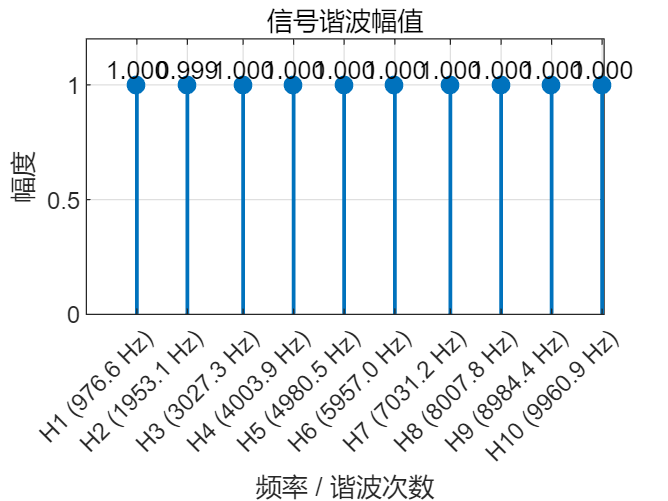

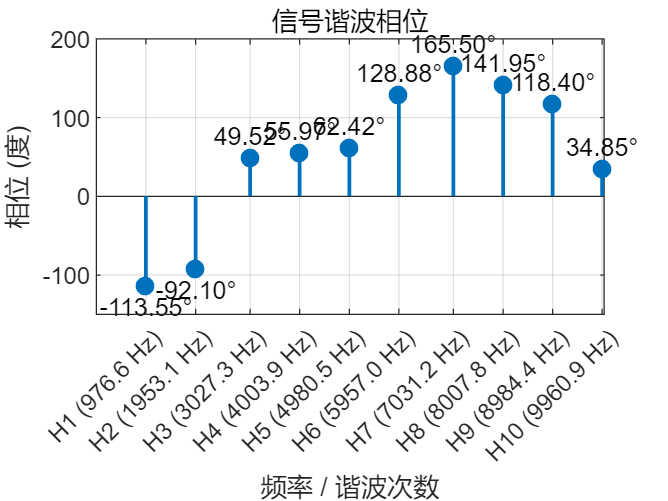


% 检查是否提取到任何谐波
if isempty(harmonic_freqs)
    fprintf('未提取到任何谐波。请检查基波频率设置和信号内容。\n');
else
    % --- 4. 准备要在图中显示的文本标签和横轴标签 ---

    % 1. 准备幅值数值标签 (在幅度点上方显示)
    mag_labels = cell(1, length(harmonic_mags));
    for i = 1:length(harmonic_mags)
        mag_labels{i} = sprintf('%.3f', harmonic_mags(i)); % 格式化幅值数值
    end

    % 2. 准备相位数值标签 (在相位点附近显示)
    phase_labels = cell(1, length(harmonic_phases_deg));
    for i = 1:length(harmonic_phases_deg)
        phase_labels{i} = sprintf('%.2f°', harmonic_phases_deg(i)); % 格式化相位数值，加°符号
    end

    % 3. 准备横轴标签 (例如 "H1 (50 Hz)", "H2 (100 Hz)" 等)
    x_tick_labels = cell(1, length(harmonic_freqs));
    for i = 1:length(harmonic_freqs)
        x_tick_labels{i} = sprintf('H%d (%.1f Hz)', harmonic_numbers(i), harmonic_freqs(i));
    end

    % 计算相位文本偏移量
    text_offset = max(abs(harmonic_phases_deg)) * 0.05;
    if text_offset < 5 && max(abs(harmonic_phases_deg)) > 0
        text_offset = 5;
    elseif max(abs(harmonic_phases_deg)) == 0
        text_offset = 5;
    end


    % --- 5. 绘制谐波幅值和相位 (在单独的图窗中，带数值和标签) ---

    % 绘制谐波幅值 (在单独的图窗中)
    figure; % 创建一个新的图窗
    stem(harmonic_freqs, harmonic_mags, 'filled', 'LineWidth', 1.5);
    title('信号谐波幅值');
    ylabel('幅度');
    grid on;

    ax_mag = gca; % 获取当前图窗的 Axes 对象句柄
    text(ax_mag, harmonic_freqs, harmonic_mags, mag_labels, ...
         'VerticalAlignment', 'bottom', ... % 文本底部对齐数据点 Y 值 (在点上方)
         'HorizontalAlignment', 'center');  % 文本水平中心与数据点 X 值对齐

    ax_mag.XTick = harmonic_freqs;      % 设置刻度位置在每个谐波频率处
    ax_mag.XTickLabel = x_tick_labels;  % 设置刻度标签为准备好的字符串数组
    ax_mag.XTickLabelRotation = 45;     % 旋转标签，防止文字重叠
    xlabel('频率 / 谐波次数');      % 修改横轴标签的说明
    % 可选：调整 x 轴范围，使其更紧凑
    % xlim([min(harmonic_freqs)-f_fundamental/2, max(harmonic_freqs)+f_fundamental/2]);


    % 绘制谐波相位 (在另一个单独的图窗中)
    figure; % 创建一个新的图窗
    stem(harmonic_freqs, harmonic_phases_deg, 'filled', 'LineWidth', 1.5);
    title('信号谐波相位');
    ylabel('相位 (度)'); % 在标签中注明单位
    grid on;

    ax_phase = gca; % 获取当前图窗的 Axes 对象句柄
    % 使用循环来根据相位正负调整文本位置
    for i = 1:length(harmonic_phases_deg)
        if harmonic_phases_deg(i) >= 0
            text(ax_phase, harmonic_freqs(i), harmonic_phases_deg(i) + text_offset, phase_labels{i}, ...
                 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
        else
            text(ax_phase, harmonic_freqs(i), harmonic_phases_deg(i) - text_offset, phase_labels{i}, ...
                 'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
        end
    end

    ax_phase.XTick = harmonic_freqs;      % 设置刻度位置在每个谐波频率处
    ax_phase.XTickLabel = x_tick_labels;  % 设置刻度标签为准备好的字符串数组
    ax_phase.XTickLabelRotation = 45;     % 旋转标签
    xlabel('频率 / 谐波次数');      % 修改横轴标签的说明
    % 可选：设置 Y 轴范围，使图更清晰
    % ylim([-180, 180]);
    % 可选：调整 x 轴范围
    % xlim([min(harmonic_freqs)-f_fundamental/2, max(harmonic_freqs)+f_fundamental/2]);

    % 可选：链接 x 轴，使两个图的横轴缩放同步
    % linkaxes([ax_mag, ax_phase], 'x');
end

### 基于基波计算相位差

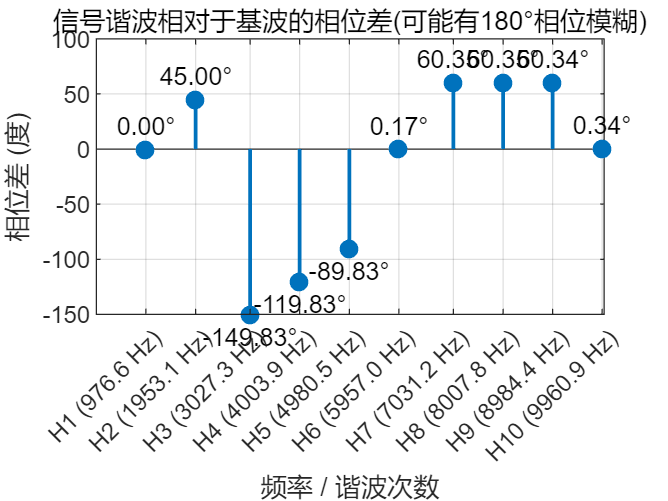

% --- 计算相对于基波的相位差 ---

% 找到基波 (第1次谐波) 在提取的谐波数组中的索引
idx_fundamental = find(harmonic_numbers == 1);

% 检查是否成功提取到基波 (如果基波幅值太小或被滤掉可能提取不到)
if isempty(idx_fundamental)
    fprintf('未找到基波 (第1次谐波)，无法计算并绘制相位差图。\n');
    % 如果没有找到基波，下面的代码将不会执行
else
    % 获取基波的相位 (以度为单位)
    phase_fundamental_deg = harmonic_phases_deg(idx_fundamental);

    % 计算每个提取到的谐波相对于基波的相位差
    % 相位差 = 谐波相位 - 基波相位
    % phase_differences_deg = harmonic_phases_deg - phase_fundamental_deg;
    phase_offset = 90;
    phase_differences_deg = zeros(size(harmonic_phases_deg));
    for i = 1:length(phase_differences_deg)
        phase_m_deg = harmonic_phases_deg(i);
        phase_differences_deg(i) = phase_m_deg - i * phase_fundamental_deg - (i-1)*phase_offset;
        % phase_differences_deg(i) = phase_m_deg - phase_fundamental_deg;
    end
    % 将计算出的相位差规整到 -180 到 +180 度之间
    % 例如，如果相位差是 200 度，规整后是 -160 度 (200 - 360)
    % 如果相位差是 -200 度，规整后是 160 度 (-200 + 360)
    phase_differences_wrapped_deg = wrapTo180(phase_differences_deg);

    % --- 准备相位差的数值标签 ---
    phase_diff_labels = cell(1, length(phase_differences_wrapped_deg));
    for i = 1:length(phase_differences_wrapped_deg)
        % 格式化相位差数值，保留2位小数并加上°符号
        phase_diff_labels{i} = sprintf('%.2f°', phase_differences_wrapped_deg(i));
    end

    % --- 绘制相位差图 ---

    figure; % 创建一个新的图窗用于相位差谱
    % 绘制相位差
    % 横轴仍然使用谐波频率作为 Stem 的位置
    stem(harmonic_freqs, phase_differences_wrapped_deg, 'filled', 'LineWidth', 1.5);
    title('信号谐波相对于基波的相位差(可能有180°相位模糊)');
    ylabel('相位差 (度)'); % Y轴标签明确表示单位是“度”
    grid on;

    ax_phase_diff = gca; % 获取当前图窗的 Axes 对象句柄

    % 在每个相位差点附近显示数值标签
    % 计算文本偏移量，基于相位差的范围
    text_offset_diff = max(abs(phase_differences_wrapped_deg)) * 0.05;
     % 确保偏移量不会太小或为零，避免文本和点重叠
    if text_offset_diff < 5 && max(abs(phase_differences_wrapped_deg)) > 0
        text_offset_diff = 5;
    elseif max(abs(phase_differences_wrapped_deg)) == 0
        text_offset_diff = 5;
    end

    for i = 1:length(phase_differences_wrapped_deg)
        % 根据相位差值的正负调整文本位置 (上方或下方)
        if phase_differences_wrapped_deg(i) >= 0
            text(ax_phase_diff, harmonic_freqs(i), phase_differences_wrapped_deg(i) + text_offset_diff, phase_diff_labels{i}, ...
                 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
        else
            text(ax_phase_diff, harmonic_freqs(i), phase_differences_wrapped_deg(i) - text_offset_diff, phase_diff_labels{i}, ...
                 'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
        end
    end

    % 设置横轴刻度位置和标签 (使用之前准备好的组合标签)
    ax_phase_diff.XTick = harmonic_freqs;
    ax_phase_diff.XTickLabel = x_tick_labels;
    ax_phase_diff.XTickLabelRotation = 45; % 旋转标签
    xlabel('频率 / 谐波次数'); % 横轴标签说明

    % 可选：设置 Y 轴范围，使图更清晰，例如覆盖 -180 到 180 度
    % ylim([-180, 180]);
    % 可选：调整 x 轴范围，使其更紧凑
    % xlim([min(harmonic_freqs)-fundamental_freq/2, max(harmonic_freqs)+fundamental_freq/2]);
end

### 进行频率插值获取相位（不精准但是不会出现180°的相位模糊）

% 利用频率插值测量相位时，需要对采样数组加不同的窗
window_blackman = blackman(L_signal);% Blackman 窗

% 2. 将时域信号与窗函数逐点相乘
% 这就是“加窗”操作
adcResult_windowed_blackman = adcResult(:) .* window_blackman(:); % 使用 (:) 确保逐点乘法正确进行

fft_result_windowed_blackman = fft(adcResult_windowed_blackman, N_fft);


% 提取单边谱的复数结果 (用于插值)
fft_single_sided_complex = fft_result_windowed_blackman(1:num_single_sided_points);
% 初始化用于存储插值后结果的数组
harmonic_freqs_interpolated = [];
harmonic_phases_deg_interpolated = []; % 存储插值后的相位 (度)
harmonic_numbers_interpolated = []; % 存储是第几次谐波

fprintf('进行频域插值以获取更精确的相位...\n');

进行频域插值以获取更精确的相位...



% 遍历可能的谐波次数
for m = 1:max_harmonic_num_manual
    target_freq = m * f_fundamental;

    % 1. 基于幅度谱找到该谐波的峰值 Bin 索引 (1-based)
    % 计算该理论频率在 N_fft 点 FFT 中的 0-based Bin 索引
    estimated_index_Nfft = round(target_freq * N_fft / Fs);
    % 转换为单边谱的 1-based 索引
    peak_index_1based = estimated_index_Nfft + 1;

    % --- 2. 检查该峰值 Bin 索引是否允许进行 3 点插值 ---
    % 需要索引大于 1 且小于 num_single_sided_points
    if peak_index_1based > 1 && peak_index_1based < num_single_sided_points

        % 3. 提取峰值 Bin 及其左右邻居的复数 FFT 值 (共 3 个)
        complex_values_around_peak = fft_single_sided_complex(peak_index_1based - 1 : peak_index_1based + 1);

        % 4. 提取对应的 Bin 索引 (1-based)
        bin_indices_for_interp = (peak_index_1based - 1 : peak_index_1based + 1)'; % 确保是列向量

        % --- 5. 调用插值函数进行计算 ---
        [estimated_true_freq, estimated_complex_value_interp] = interpolateComplexLogQuadratic(complex_values_around_peak, bin_indices_for_interp, Fs, N_fft);

        % 6. 从插值得到的复数值中提取相位 (以度为单位)
        estimated_phase_rad_interp = angle(estimated_complex_value_interp);
        estimated_phase_deg_interp = rad2deg(estimated_phase_rad_interp);

        % 7. 存储结果
        harmonic_numbers_interpolated = [harmonic_numbers_interpolated, m];
        harmonic_freqs_interpolated = [harmonic_freqs_interpolated, estimated_true_freq];

        % *** 重点：存储用于绘图的幅值。这里保留你认为准确的幅值测量结果。***
        % 你需要找到在插值得到的频率 estimated_true_freq 处对应的“准确”幅值。
        % 最简单的方法是使用之前计算出的 scaled 幅度谱数组 (magnitude_single_sided_scaled)，
        % 找到 closest index 或者在该 interpolated 频率处进行幅度插值（如果你愿意）。
        % 如果你对原方法找峰值 bin 索引处的幅度满意，可以直接用那个。
        % 假设 magnitude_single_sided_scaled 是前面计算出的基于 N_fft 和窗函数修正的单边幅度谱
        % 查找离 estimated_true_freq 最近的 Bin 索引，获取其幅度
        [~, closest_bin_idx] = min(abs(f_single_sided - estimated_true_freq));

        % 或者，如果你相信插值得到的幅值更准确 (interpolateComplexLogQuadratic 也会输出插值幅值)
         accurate_mag_at_interp_freq = abs(estimated_complex_value_interp); % 示例：使用插值得到的幅值

        harmonic_phases_deg_interpolated = [harmonic_phases_deg_interpolated, estimated_phase_deg_interp];


        fprintf('  %d 次谐波 (原Bin %d): 插值频率 %.2f Hz, 用于绘图幅值 %.4f, 插值相位 %.2f 度\n', ...
                 m, peak_index_1based, estimated_true_freq, accurate_mag_at_interp_freq, estimated_phase_deg_interp);

    else
        % 处理边界情况 (峰值 Bin 索引是 1 或 num_single_sided_points)
        % 在这些情况下 3 点插值不适用。可以跳过，或者单独处理 (例如使用 2 点插值)。
        % 为了简单，这里选择跳过插值，直接使用峰值 Bin 的值（精度较低）或者跳过该谐波。
         fprintf('  %d 次谐波 (Bin %d) 靠近边界或无法插值 (幅值过低？)。跳过精确插值。\n', m, peak_index_1based);
         % 可选：在这里将原峰值 Bin 的值添加到结果数组中，但不标记为插值
         % harmonic_numbers_interpolated = [harmonic_numbers_interpolated, m];
         % harmonic_freqs_interpolated = [harmonic_freqs_interpolated, f_single_sided(peak_index_1based)];
         % harmonic_mags_for_plot = [harmonic_mags_for_plot, magnitude_single_sided_scaled(peak_index_1based)]; % 使用缩放后的幅度
         % harmonic_phases_deg_interpolated = [harmonic_phases_deg_interpolated, rad2deg(angle(fft_single_sided_complex(peak_index_1based)))]; % 使用原 Bin 相位
    end
end

  1 次谐波 (原Bin 11): 插值频率 1098.32 Hz, 用于绘图幅值 1.9586, 插值相位 -157.91 度
  2 次谐波 (原Bin 21): 插值频率 2097.75 Hz, 用于绘图幅值 2.3578, 插值相位 -178.62 度
  3 次谐波 (原Bin 32): 插值频率 3097.12 Hz, 用于绘图幅值 2.0024, 插值相位 100.97 度
  4 次谐波 (原Bin 42): 插值频率 4097.55 Hz, 用于绘图幅值 1.8412, 插值相位 63.39 度
  5 次谐波 (原Bin 52): 插值频率 5098.36 Hz, 用于绘图幅值 1.9239, 插值相位 25.28 度
  6 次谐波 (原Bin 62): 插值频率 6098.01 Hz, 用于绘图幅值 2.2732, 插值相位 49.13 度
  7 次谐波 (原Bin 73): 插值频率 7097.16 Hz, 用于绘图幅值 2.0652, 插值相位 -135.93 度
  8 次谐波 (原Bin 83): 插值频率 8097.40 Hz, 用于绘图幅值 1.8534, 插值相位 156.82 度
  9 次谐波 (原Bin 93): 插值频率 9098.00 Hz, 用于绘图幅值 1.8954, 插值相位 88.87 度
  10 次谐波 (原Bin 103): 插值频率 10098.02 Hz, 用于绘图幅值 2.1880, 插值相位 -37.85 度


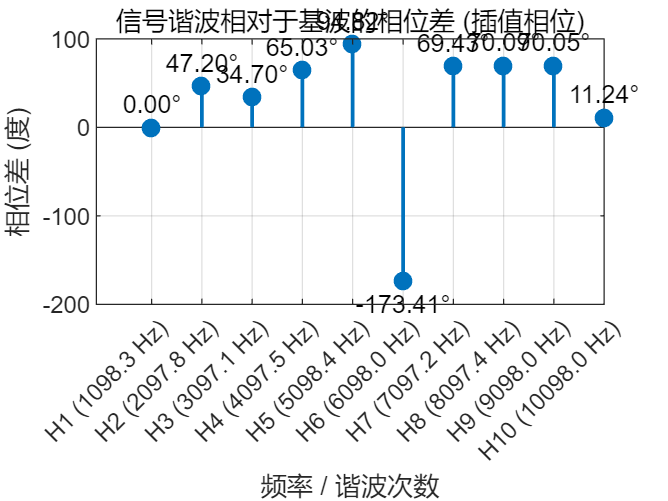


% --- 检查是否提取并插值到任何谐波 ---
if isempty(harmonic_freqs_interpolated)
    fprintf('未找到或无法插值任何谐波。请检查基波频率设置、信号内容、或 FFT 参数。\n');
else
    % --- 准备要在图中显示的文本标签和横轴标签 (基于插值结果) ---
    % 2. 准备相位数值标签 (使用插值相位)
    phase_labels_interp = cell(1, length(harmonic_phases_deg_interpolated));
    for i = 1:length(harmonic_phases_deg_interpolated)
        phase_labels_interp{i} = sprintf('%.2f°', harmonic_phases_deg_interpolated(i));
    end

    % 3. 准备横轴标签 (频率 + 谐波次数) (使用插值频率)
    x_tick_labels_interp = cell(1, length(harmonic_freqs_interpolated));
    for i = 1:length(harmonic_freqs_interpolated)
        x_tick_labels_interp{i} = sprintf('H%d (%.1f Hz)', harmonic_numbers_interpolated(i), harmonic_freqs_interpolated(i));
    end

    % 计算相位文本偏移量
    text_offset_interp = max(abs(harmonic_phases_deg_interpolated)) * 0.05;
     if text_offset_interp < 5 && max(abs(harmonic_phases_deg_interpolated)) > 0
        text_offset_interp = 5;
     elseif max(abs(harmonic_phases_deg_interpolated)) == 0
        text_offset_interp = 5;
     end


    % --- 计算相对于基波的相位差 (使用插值相位) ---
    idx_fundamental_interp = find(harmonic_numbers_interpolated == 1);

    if isempty(idx_fundamental_interp)
        fprintf('基波 (第1次谐波) 未在插值结果中找到。无法计算相位差图。\n');
        % 跳过绘制相位差图
    else
        phase_fundamental_deg_interp = harmonic_phases_deg_interpolated(idx_fundamental_interp);

        % phase_differences_deg_interp = harmonic_phases_deg_interpolated - phase_fundamental_deg_interp;
        
        phase_offset = 90;
        for i = 1:length(harmonic_phases_deg_interpolated)
            phase_m_deg = harmonic_phases_deg_interpolated(i);
            phase_differences_deg_interp(i) = phase_m_deg - i * phase_fundamental_deg_interp - (i-1)*phase_offset;
        % phase_differences_deg(i) = phase_m_deg - phase_fundamental_deg;
        end

        phase_differences_wrapped_deg_interp = wrapTo180(phase_differences_deg_interp);

        % 准备相位差标签
        phase_diff_labels_interp = cell(1, length(phase_differences_wrapped_deg_interp));
        for i = 1:length(phase_differences_wrapped_deg_interp)
             phase_diff_labels_interp{i} = sprintf('%.2f°', phase_differences_wrapped_deg_interp(i));
        end

        % --- 绘制插值后的相位差图 ---
        figure;
        stem(harmonic_freqs_interpolated, phase_differences_wrapped_deg_interp, 'filled', 'LineWidth', 1.5);
        title('信号谐波相对于基波的相位差 (插值相位)');
        ylabel('相位差 (度)');
        grid on;

        ax_phase_diff_interp = gca;
        for i = 1:length(phase_differences_wrapped_deg_interp)
            if phase_differences_wrapped_deg_interp(i) >= 0
                text(ax_phase_diff_interp, harmonic_freqs_interpolated(i), phase_differences_wrapped_deg_interp(i) + text_offset_interp, phase_diff_labels_interp{i}, ...
                     'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
            else
                text(ax_phase_diff_interp, harmonic_freqs_interpolated(i), phase_differences_wrapped_deg_interp(i) - text_offset_interp, phase_diff_labels_interp{i}, ...
                     'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
            end
        end

        ax_phase_diff_interp.XTick = harmonic_freqs_interpolated;
        ax_phase_diff_interp.XTickLabel = x_tick_labels_interp;
        ax_phase_diff_interp.XTickLabelRotation = 45;
        xlabel('频率 / 谐波次数');

        % Optional: ylim([-180, 180]);
    end

end % End if not empty harmonic_freqs_interpolated

### 利用未频率插值和频率插值得到的相位数组得到最终的相位（解决180°相位模糊问题）

% --- 接在计算出 phase_differences_wrapped_deg (原Bin相位差) 和 phase_differences_wrapped_deg_interp (插值相位差) 的代码之后 ---

% 确保以下变量是可用的，并且包含了相同谐波点的结果：
% harmonic_numbers_interpolated    % 谐波次数数组 (例如 [1 2 3 ...])
% harmonic_freqs      % 对应的频率数组 (作为绘图横轴)
% phase_differences_wrapped_deg    % 从原 Bin 相位计算并规整的相位差 (可能存在 180° 模糊)
% phase_differences_wrapped_deg_interp % 从插值相位计算并规整的相位差 (没有 180° 模糊)
% x_tick_labels_interp             % 横轴标签

% 确保这两个相位差数组的长度是相同的，对应相同的谐波点
if length(phase_differences_wrapped_deg) ~= length(phase_differences_wrapped_deg_interp)
    error('用于解决模糊的相位差数组长度必须相同。');
end

num_harmonics_to_resolve = length(phase_differences_wrapped_deg);

% 初始化存储解决了 180 度模糊后的最终相位差数组
phase_diff_resolved_deg = zeros(1, num_harmonics_to_resolve);

fprintf('利用插值结果解决 180 度相位模糊...\n');

利用插值结果解决 180 度相位模糊...


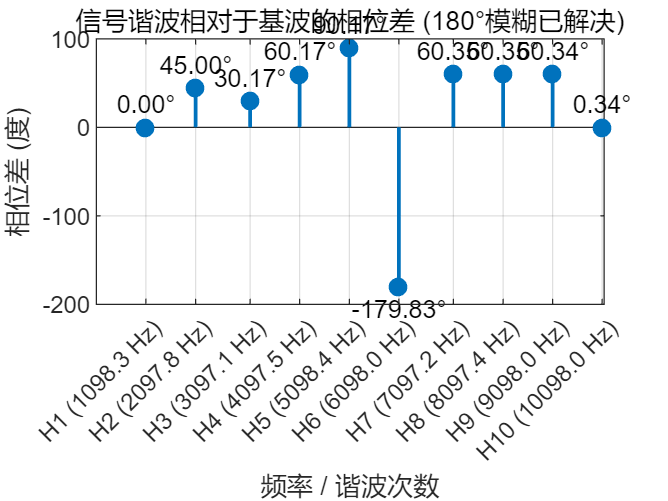


% 遍历每一个谐波点
for i = 1:num_harmonics_to_resolve
    % 从原 Bin 相位得到的相位差
    raw_phase_diff = phase_differences_wrapped_deg(i);

    % 从插值得到的相位差
    interp_phase_diff = phase_differences_wrapped_deg_interp(i);

    % --- 定义两个可能的候选相位差 ---
    % 候选 1：原始相位差本身
    candidate1 = raw_phase_diff;
    % 候选 2：原始相位差加上 180 度后再规整到 +/-180 度
    % wrapTo180(x + 180) 可以有效地得到 x + 180 度在 +/-180 范围内的等效角度
    candidate2 = wrapTo180(raw_phase_diff + 180);

    % --- 比较两个候选相位差，看哪个更接近插值得到的相位差 ---
    % 计算每个候选相位差与插值相位差之间的“距离”（在 +/-180 度范围内）
    distance1 = wrapTo180(candidate1 - interp_phase_diff);
    distance2 = wrapTo180(candidate2 - interp_phase_diff);

    % 比较距离的绝对值
    if abs(distance1) <= abs(distance2)
        % 如果候选 1 更接近（或同样接近）插值结果
        % 则认为解决了 180 度模糊后的相位差就是候选 1
        phase_diff_resolved_deg(i) = candidate1;
    else
        % 如果候选 2 更接近插值结果
        % 则认为解决了 180 度模糊后的相位差就是候选 2
        phase_diff_resolved_deg(i) = candidate2;
    end
end

% 现在，phase_diff_resolved_deg 数组中存储了解决了 180 度模糊后的相位差。
% 你可以使用它来绘制最终的相位差图。

% --- 准备解决模糊后的相位差数值标签 ---
phase_diff_labels_resolved = cell(1, num_harmonics_to_resolve);
for i = 0:num_harmonics_to_resolve-1
     phase_diff_labels_resolved{i+1} = sprintf('%.2f°', phase_diff_resolved_deg(i+1));
end

% 计算文本偏移量
text_offset_resolved = max(abs(phase_diff_resolved_deg)) * 0.05;
 if text_offset_resolved < 5 && max(abs(phase_diff_resolved_deg)) > 0
    text_offset_resolved = 5;
 elseif max(abs(phase_diff_resolved_deg)) == 0
    text_offset_resolved = 5;
 end

% --- 绘制解决了 180 度模糊后的相位差图 ---
figure;
% 横轴位置使用插值频率 (或者你认为准确的频率)
stem(harmonic_freqs, phase_diff_resolved_deg, 'filled', 'LineWidth', 1.5);

% 更新图的标题
title('信号谐波相对于基波的相位差 (180°模糊已解决)');
ylabel('相位差 (度)'); % Y轴标签仍然是度
grid on;

ax_phase_diff_resolved = gca;
% 添加数值标签
for i = 1:num_harmonics_to_resolve
    if phase_diff_resolved_deg(i) >= 0
        text(ax_phase_diff_resolved, harmonic_freqs(i), phase_diff_resolved_deg(i) + text_offset_resolved, phase_diff_labels_resolved{i}, ...
             'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
    else
        text(ax_phase_diff_resolved, harmonic_freqs(i), phase_diff_resolved_deg(i) - text_offset_resolved, phase_diff_labels_resolved{i}, ...
             'VerticalAlignment', 'top', 'HorizontalAlignment', 'center');
    end
end

% 设置横轴刻度位置和标签 (使用插值频率对应的标签)
% 假设 x_tick_labels_interp 已经从前面计算好
ax_phase_diff_resolved.XTick = harmonic_freqs;
ax_phase_diff_resolved.XTickLabel = x_tick_labels_interp;
ax_phase_diff_resolved.XTickLabelRotation = 45; % 旋转标签
xlabel('频率 / 谐波次数'); % 横轴标签


% 可选：设置 Y 轴范围
% ylim([-180, 180]);

% 可选：如果需要，可以链接这个图的横轴与幅值图的横轴
% if exist('ax_mag_interp', 'var')
%     linkaxes([ax_mag_interp, ax_phase_diff_resolved], 'x');
% end

### 频率插值算法：实现二次复数对数插值函数

% --- 实现二次复数对数插值函数 ---
% 这个函数用于接收峰值 Bin 及其左右邻居的复数 FFT 值，返回插值得到的频率和复数值

function [estimated_freq, estimated_complex_value] = interpolateComplexLogQuadratic(complex_values_3pts, bin_indices_3pts, Fs, N_fft)
    % 输入:
    %   complex_values_3pts: 包含峰值 Bin 及其左右邻居的 3 个复数 FFT 值 [X_{k-1}; X_k; X_{k+1}]
    %   bin_indices_3pts: 对应的 3 个 Bin 索引 (1-based), 例如 [k-1; k; k+1]
    %   Fs: 采样频率
    %   N_fft: FFT 点数
    % 输出:
    %   estimated_freq: 插值得到的频率 (Hz)
    %   estimated_complex_value: 插值得到的该频率点处的复数值

    if length(complex_values_3pts) ~= 3 || length(bin_indices_3pts) ~= 3
        error('interpolateComplexLogQuadratic requires exactly 3 complex values and their bin indices.');
    end

    % 1. 计算复数对数，并对相位进行解卷绕 (Unwrap)
    % log(X) = log(|X|) + j * angle(X)
    log_complex_values = log(complex_values_3pts);

    % 对虚部 (相位) 进行解卷绕，这是准确插值的关键
    log_phase_unwrapped = unwrap(imag(log_complex_values));

    % 重构解卷绕后的复数对数值
    log_complex_values_unwrapped = real(log_complex_values) + 1j * log_phase_unwrapped;

    % 2. 对解卷绕后的复数对数值进行二次多项式拟合
    % 我们要拟合 log_complex_values_unwrapped = a * (bin_index)^2 + b * (bin_index) + c
    % 使用 bin_indices_3pts 作为 x 值
    x = bin_indices_3pts;
    y = log_complex_values_unwrapped;

    % 构建 Vandermonde 矩阵进行二次拟合 [x^2 x 1]
    X_matrix = [x.^2, x, ones(3, 1)];

    % 求解复数系数 [a; b; c]
    coeffs = X_matrix \ y; % 使用最小二乘求解，对于 3 个点是精确解

    a = coeffs(1); % 复数系数 a
    b = coeffs(2); % 复数系数 b
    c = coeffs(3); % 复数系数 c

    % 3. 找到拟合抛物线的峰值位置 (在 Bin 索引坐标系中)
    % 峰值在 x = -b / (2a)
    % 这里的 x 是 Bin 索引
    % 理论上峰值位置可能是复数，但频率对应于其实部
    estimated_peak_bin_index_float = -b / (2 * a);

    % 我们需要峰值位置的实部作为 Bin 索引的估计值
    estimated_peak_bin_index_float_real = real(estimated_peak_bin_index_float);

    % 4. 将估计的峰值 Bin 索引转换为频率 (Hz)
    % 频率 = Bin 索引 * Fs / N_fft
    estimated_freq = estimated_peak_bin_index_float_real * Fs / N_fft;

    % 5. 在估计的峰值 Bin 索引处评估拟合的抛物线，得到估计的复数对数值
    % 注意：这里使用估计的峰值 Bin 索引的复数形式 estimated_peak_bin_index_float
    log_complex_value_at_peak = a * estimated_peak_bin_index_float.^2 + b * estimated_peak_bin_index_float + c;

    % 6. 将估计的复数对数值转换回普通的复数 FFT 值
    estimated_complex_value = exp(log_complex_value_at_peak);

    % 7. 返回估计的频率和复数 FFT 值
    % 调用者可以从 estimated_complex_value 中提取幅值和相位
end % function interpolateComplexLogQuadratic
